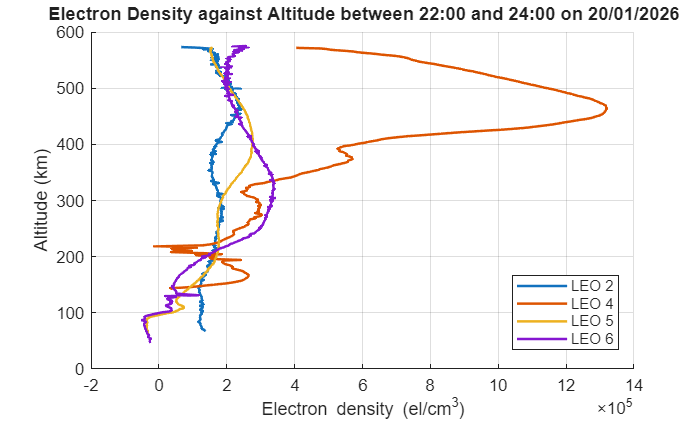

% Compare Electron Density of all LEOs at a specific moment
for target_hour = 23
target_minute = 00;
target_alt = 400;
minHour = target_hour-1;
maxHour = target_hour+1;
figure
hold on
legend_entries = strings(6,1);
for leo = 1:6
    match_idx = [];
    for i = 1:length(COSMIC_data)
        if COSMIC_data{i}.LEO_ID == leo && ...
           COSMIC_data{i}.hour == target_hour && ...
           abs(COSMIC_data{i}.minute - target_minute) <= 10
            match_idx = i;
            break
        end
    end
    if ~isempty(match_idx)
        ELEC_DENS = COSMIC_data{match_idx}.ELEC_dens;
        ALT = COSMIC_data{match_idx}.MSL_alt;
        plot(ELEC_DENS, ALT, 'LineWidth', 1.5)
        legend_entries(leo) = "LEO " + leo;
    end
end
xlabel('Electron density (el/cm^3)')
ylabel('Altitude (km)')
title_str = sprintf('Electron Density against Altitude between %02d:00 and %02d:00 on %02d/01/2026', ...
    minHour, maxHour, day);
t = title(title_str, 'FontSize', 11, 'Units', 'normalized');
t.Position(2) = 1.02;
legend(legend_entries(legend_entries ~= ""), 'Location','best')
grid on
hold off

end